# Estadística: La venganza

## Importar datos

load("D:\Documents\UNAM\Semestre 6\A&P_Señales\Prácticas\Utils4SP\Datasets\S5_Estadistica101_LaVenganza.mat");


## Plot de exploración

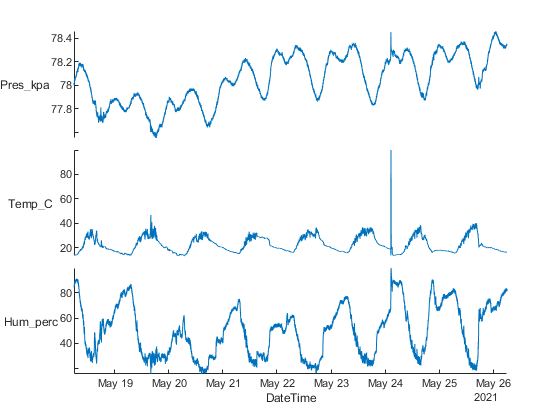

figure
stackedplot(atmosfera, 'XVariable','DateTime')


summary(atmosfera)

Variables:

    Fecha: 137522×1 cell array of character vectors

    Hora: 137522×1 cell array of character vectors

    Pres_kpa: 137522×1 double

        Values:

            Min        77.55  
            Median     78.06  
            Max        78.46  

    Temp_C: 137522×1 double

        Values:

            Min             13.38  
            Median          21.01  
            Max             100    
            NumMissing      11     

    Hum_perc: 137522×1 double

        Values:

            Min             15.27  
            Median          50.16  
            Max             99.97  
            NumMissing      61     

    DateTime: 137522×1 datetime

        Values:

            Min       20210518 06:00:03
            Median    20210522 05:59:48
            Max       20210526 05:59:55



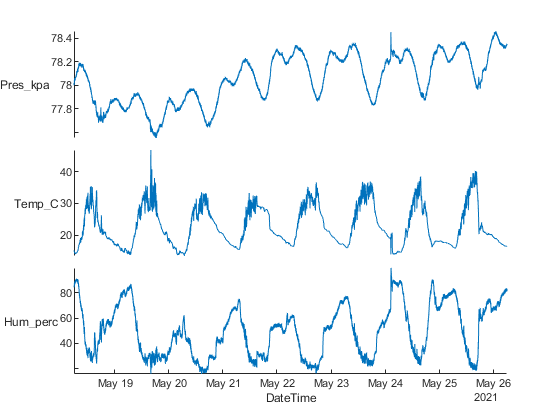


%elementos/lecturas de atmosfera tq 
%existen Nan en su campo de humedad
%y te enseña todos los datos que le acompañan
atmosfera(ismissing(atmosfera.Hum_perc),:); % ; no muestra tabla

%lectruras de atmos tq
%Existen Nan en su temp
%y te enseña todos los datos que le acompañan
atmosfera(ismissing(atmosfera.Temp_C),:);


%Con los [] en lugar de : podemos pedir columnas en partícular
%Los : te avientan todas las columnas
atmosfera(ismissing(atmosfera.Temp_C),["DateTime","Hum_perc"]);

%Quitemos los NaNs
atmosfera_clean=rmmissing(atmosfera);

figure
stackedplot(atmosfera_clean,'XVariable','DateTime')

## Métricas de tendencia central

%Veamos la humedad (de la tabla limpia) en histograma y box plot
% figure
% tiledlayout(1,2)
% nexttile
% boxplot(atmosfera_clean.Hum_perc)
% xlabel("Humedad relativa [%]")
% ylabel("porcentaje")
% 
% nexttile
% histogram(atmosfera_clean.Hum_perc,'BinWidth',5,'Normalization',"probability")
% xlabel("Humedad relativa [%]")
% ylabel("Probabilidad")
% 
% figure
% plot(atmosfera_clean.DateTime,atmosfera_clean.Hum_perc)
% ylabel("Humedad relativa [%]")
% grid on

%Promedio
hum_mean=mean(atmosfera_clean.Hum_perc)

hum_mean = 49.6841

%Mediana
hum_median=median(atmosfera_clean.Hum_perc)

hum_median = 50.1550

%Moda
hum_mode=mode(atmosfera_clean.Hum_perc)

hum_mode = 28.9200

%Cuantiles
hum_1Q=quantile(atmosfera_clean.Hum_perc,0.25)

hum_1Q = 29.8800

hum_3Q=quantile(atmosfera_clean.Hum_perc,0.75)

hum_3Q = 66.9600


%Metemos promedio y mediana a las gráicas
figure
tiledlayout(1,2)
nexttile
boxplot(atmosfera_clean.Hum_perc)

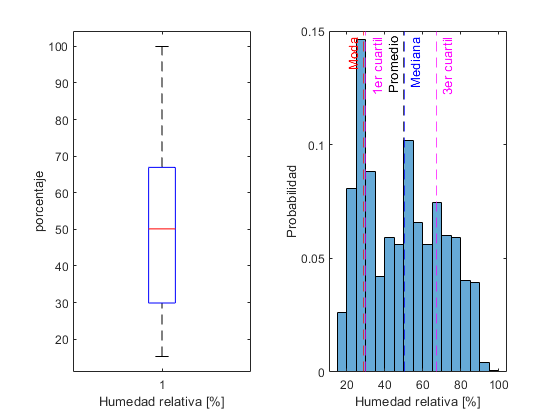

xlabel("Humedad relativa [%]")
ylabel("porcentaje")

nexttile
histogram(atmosfera_clean.Hum_perc,'BinWidth',5,'Normalization',"probability")
hold on
xline(hum_median,'--b','Mediana')
xline(hum_mean,'--k','Promedio',"LabelHorizontalAlignment", "Left")
xline(hum_mode,'--r','Moda',"LabelHorizontalAlignment", "Left")
xline(hum_1Q,'--m',"1er cuartil")
xline(hum_3Q,'--m',"3er cuartil")

xlabel("Humedad relativa [%]")
ylabel("Probabilidad")

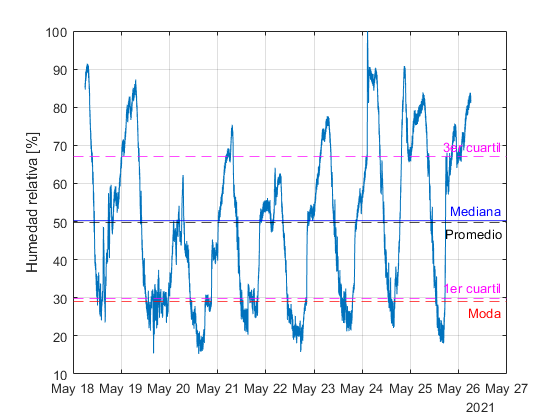


%Serie de tiempo
figure
plot(atmosfera_clean.DateTime,atmosfera_clean.Hum_perc)
ylabel("Humedad relativa [%]")
hold on
yline(hum_median,'b','Mediana')
yline(hum_mean,'--k','Promedio',"LabelVerticalAlignment","Bottom")
yline(hum_mode,'--r','Moda',"LabelVerticalAlignment","Bottom")
yline(hum_1Q,'--m',"1er cuartil")
yline(hum_3Q,'--m',"3er cuartil")
grid on
hold off

## Dispersión

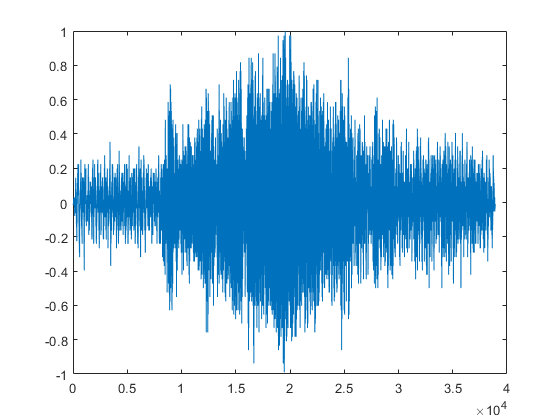

buho_left=buho(:,1);
plot(buho_left)

%Encontremos desv. est, var y promedio
buho_S=std(buho_left)

buho_S = 0.2124

buho_V=var(buho_left)

buho_V = 0.0451

buho_prom=mean(buho_left)

buho_prom = 8.1547e-08


figure
tiledlayout(1,2)
nexttile
boxplot(buho_left)

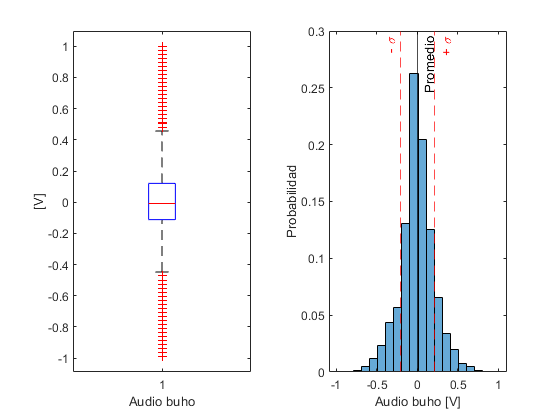

xlabel("Audio buho")
ylabel("[V]")

nexttile
histogram(buho_left,20,'Normalization',"probability")
hold on
xline(buho_prom + buho_S,'--r','+ \sigma',"LabelHorizontalAlignment", "Right")
xline(buho_prom,'k',"Promedio")
xline(buho_prom - buho_S,'--r', '- \sigma', "LabelHorizontalAlignment", "Left")
xlabel("Audio buho [V]")
ylabel("Probabilidad")
hold off

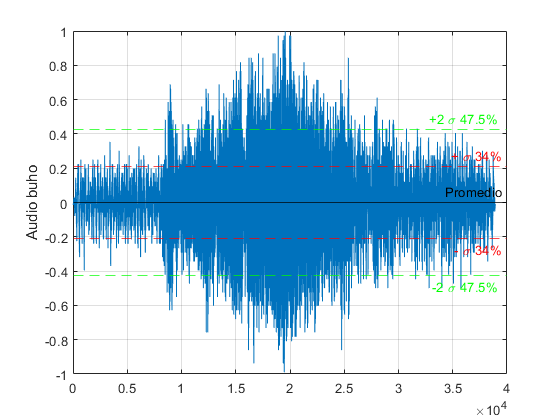


figure
plot(buho_left)
hold on
yline(buho_prom + buho_S,'--r','+ \sigma 34%')
yline(buho_prom,'k',"Promedio")
yline(buho_prom - buho_S,'--r', '- \sigma 34%',"LabelVerticalAlignment","Bottom")

yline(buho_prom + 2*buho_S,'--g','+2 \sigma 47.5% ')
yline(buho_prom - 2*buho_S,'--g', '-2 \sigma 47.5% ',"LabelVerticalAlignment","Bottom")

ylabel("Audio buho")
grid on
hold off

## Ajustes

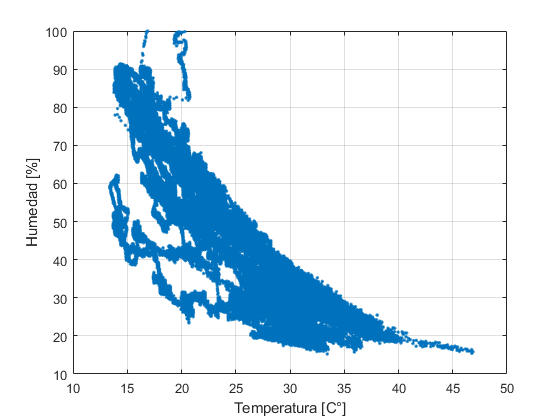

plot(atmosfera_clean.Temp_C,atmosfera_clean.Hum_perc,'.')
xlabel("Temperatura [C°]")
ylabel("Humedad [%]")
grid on


[fit_rel,gof]=fit(atmosfera_clean.Temp_C,atmosfera_clean.Hum_perc,'poly1')

fit_rel =      Linear model Poly1:
     fit_rel(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -2.772  (-2.781, -2.763)
       p2 =       113.2  (112.9, 113.4)

gof = struct with fields:
           sse: 1.5967e+07
       rsquare: 0.7212
           dfe: 137448
    adjrsquare: 0.7212
          rmse: 10.7783


[fit_rel_2,gof]=fit(atmosfera_clean.Temp_C,atmosfera_clean.Hum_perc,'poly2')

fit_rel_2 =      Linear model Poly2:
     fit_rel_2(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =       0.088  (0.08654, 0.08946)
       p2 =      -7.097  (-7.169, -7.024)
       p3 =       162.6  (161.8, 163.5)

gof = struct with fields:
           sse: 1.4498e+07
       rsquare: 0.7468
           dfe: 137447
    adjrsquare: 0.7468
          rmse: 10.2703


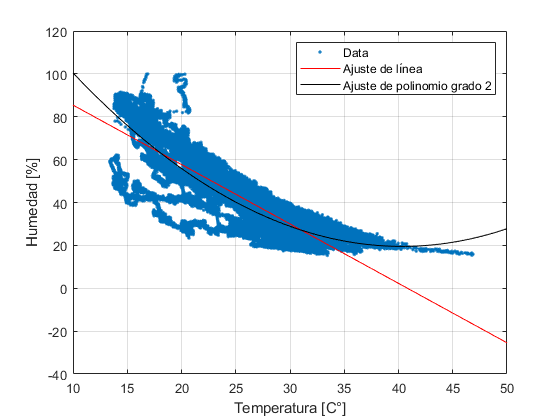

%gof=goodness of fit
%gof nos dice que tan bueno es el ajuste. Fijate en Rsquare
%arriba de 0.8~0.9 es buen ajuste

figure
plot(atmosfera_clean.Temp_C,atmosfera_clean.Hum_perc,'.')
hold on
plot(fit_rel,'r')
plot(fit_rel_2,'k')
hold off
xlabel("Temperatura [C°]")
ylabel("Humedad [%]")
legend("Data","Ajuste de línea", "Ajuste de polinomio grado 2")
grid on